numG = [0.25];
denG = [1, 0.4, 0.25];
G = tf(numG, denG);


Kp = 10;     
Ki = 0;    % Ganancia Integral

numC = [Kp, Ki];
denC = [1, 0];
C = tf(numC, denC)


C =
 
  10 s
  ----
   s
 
Continuous-time transfer function.
Model Properties


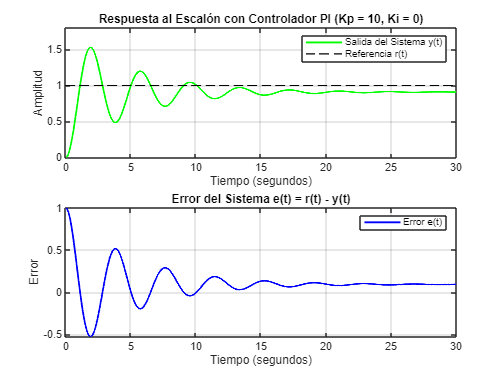



T = feedback(C * G, 1);

t = 0:0.01:30; 
[y, ~] = step(T, t); 

r = ones(size(y)); 

error = r - y;

figure(3); 

subplot(2, 1, 1); 
plot(t, y, 'g-', 'LineWidth', 1.5);
hold on;
plot(t, r, 'k--', 'LineWidth', 1); 
grid on;
title(['Respuesta al Escalón con Controlador PI (Kp = ', num2str(Kp), ', Ki = ', num2str(Ki), ')']);
ylabel('Amplitud');
xlabel('Tiempo (segundos)');
legend('Salida del Sistema y(t)', 'Referencia r(t)');
ylim([0, 1.8]);

subplot(2, 1, 2); 
plot(t, error, 'b-', 'LineWidth', 1.5);
grid on;
title('Error del Sistema e(t) = r(t) - y(t)');
ylabel('Error');
xlabel('Tiempo (segundos)');
legend('Error e(t)');
hold on


% Mostrar información en la consola
disp('Función de transferencia de la planta G(s):')

Función de transferencia de la planta G(s):


G


G =
 
         0.25
  ------------------
  s^2 + 0.4 s + 0.25
 
Continuous-time transfer function.
Model Properties


disp('Función de transferencia del controlador PI C(s):')

Función de transferencia del controlador PI C(s):


C


C =
 
  10 s
  ----
   s
 
Continuous-time transfer function.
Model Properties


disp('Función de transferencia del sistema controlado T(s):')

Función de transferencia del sistema controlado T(s):


T


T =
 
          2.5 s
  ----------------------
  s^3 + 0.4 s^2 + 2.75 s
 
Continuous-time transfer function.
Model Properties


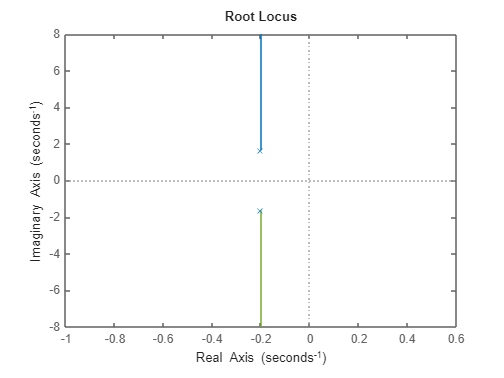

figure;
rlocus(T)